# Finding a 2D SSM for a MEMS model with more than 1 million degrees of freedom

clear all
close all

## generate model

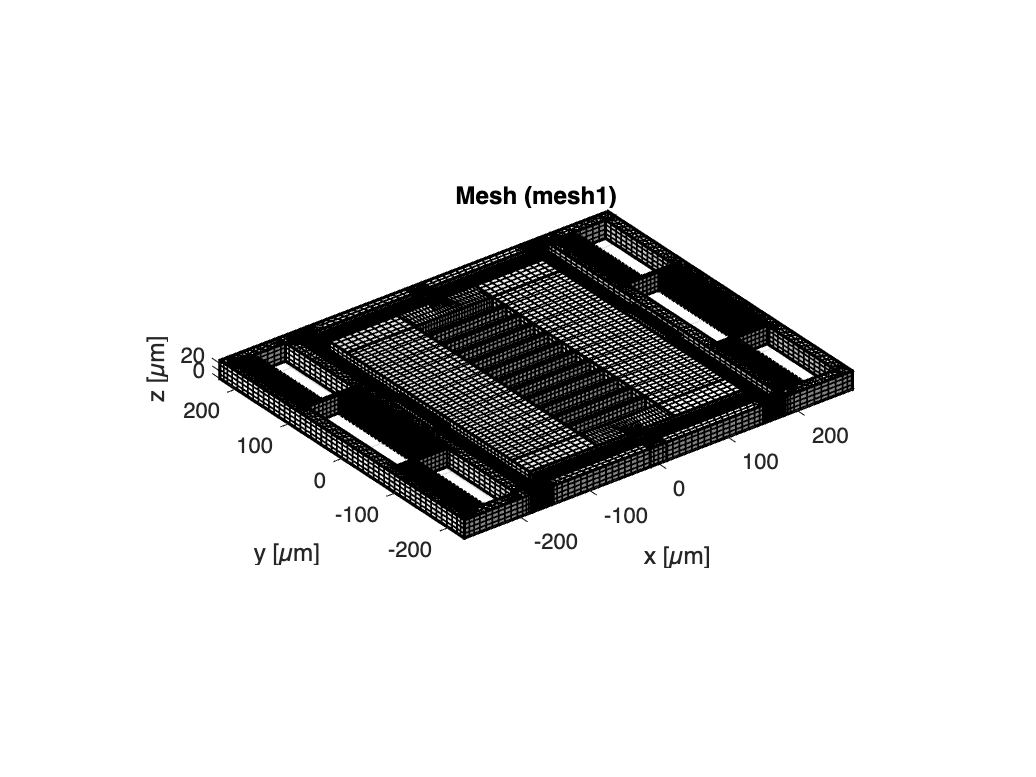

f0 = 1;
[model, M, C, K, Null, Nullf, ud, ~, out_full, u0, disp_idx] = build_model(f0);

[fint,dfint] = get_fint(K,model,Null, Nullf, ud, u0, disp_idx);


n = length(M);
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 1027278


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 2054556


## Dynamical system setup

DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K);
set(DS.Options, 'Intrusion', 'none')

set(DS,'fnl_non',fint,'dfnl_non',dfint);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')

outdof  = 643090; 
[V,D,W] = DS.linear_spectral_analysis();
Factor  = 1e-3;
DS.spectrum.V = Factor*V;
DS.spectrum.W = W/Factor;

## Choose master subspace

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex','COMPtype','second')
set(S.Options, 'solver', 'backslash'); % lsqminnorm  out of memory; linsolve does not support sparse matrix as input
masterModes = [1,2];
S.choose_E(masterModes);

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 5.000000e-03
modal damping ratio for 2 mode is 6.666667e-03
modal damping ratio for 3 mode is 2.483569e-02
modal damping ratio for 4 mode is 3.264262e-02
modal damping ratio for 5 mode is 3.807487e-02
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 10 nonzero eigenvalues are given as 
   1.0e+05 *

  -0.0078 + 1.5518i
  -0.0078 - 1.5518i
  -0.0115 + 1.7224i
  -0.0115 - 1.7224i
  -0.1002 + 4.0320i
  -0.1002 - 4.0320i
  -0.1677 + 5.1350i
  -0.1677 - 5.1350i
  -0.2254 + 5.9161i
  -0.2254 - 5.9161i

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 29
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     

## SSM computations

setup options

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     2     1
     3     1
     3     2
     4     2
     4     3
     5     3
     5     4
     6     4
     0     2
     1     2
     1     3
     2     3
     2     4
     3     4
     3     5
     4     5
     4     6
     2     0
     3     0
     3     1
     4     1
     4     2
     5     2
     5     3
     6     3
     6     4
     0     2
     0     3
     1     3
     1     4
     2     4
     2     5
     3     5
     3     6
     4     6
     3     0
     4     0
     4     1
     5     1
     5     2
     6     2
     6     3
     7     3
     0     3
     0     4
     1     4
     1     5
     2     5
     2     6
     3     6
     3     7
     3     0
     4     0
     4     1
     5     1
     5     2
     6     2
     6     3
     7     3
     0     3
     0     4
     1     4
     1     5
     2     5
     2     6
     3     6
     3     7

These are in resonance with the

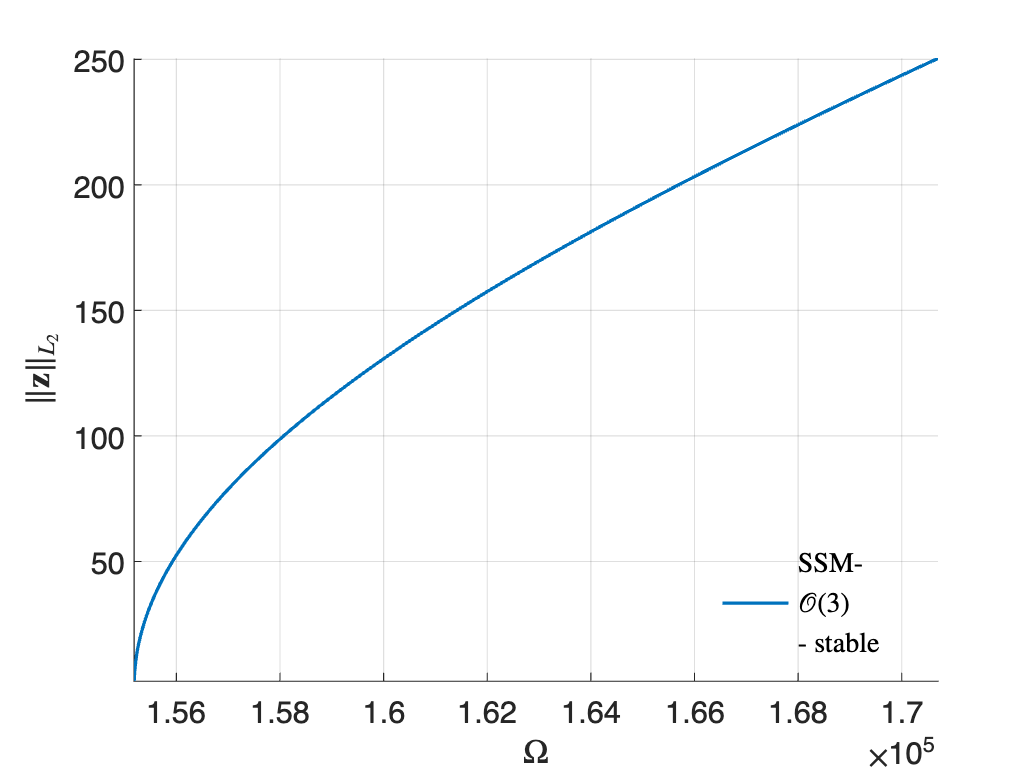

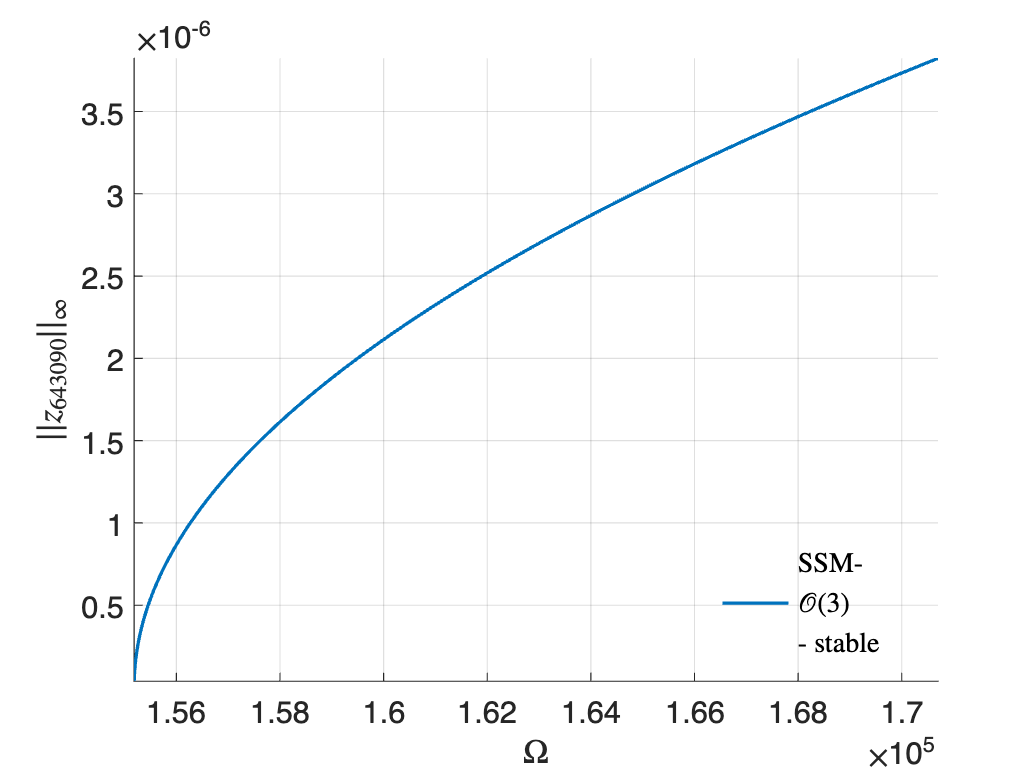

Total time spent on backbone curve computation = 01:07:40


set(S.FRCOptions, 'outdof',outdof)
set(DS.Options, 'outDOF',outdof)
set(S.Options, 'reltol', 1,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',false)
omega0 = imag(S.E.spectrum(1));
omegaRange = omega0*[0.9 1.1];

order = 3;
BB    = S.extract_backbone(masterModes, omegaRange, order);

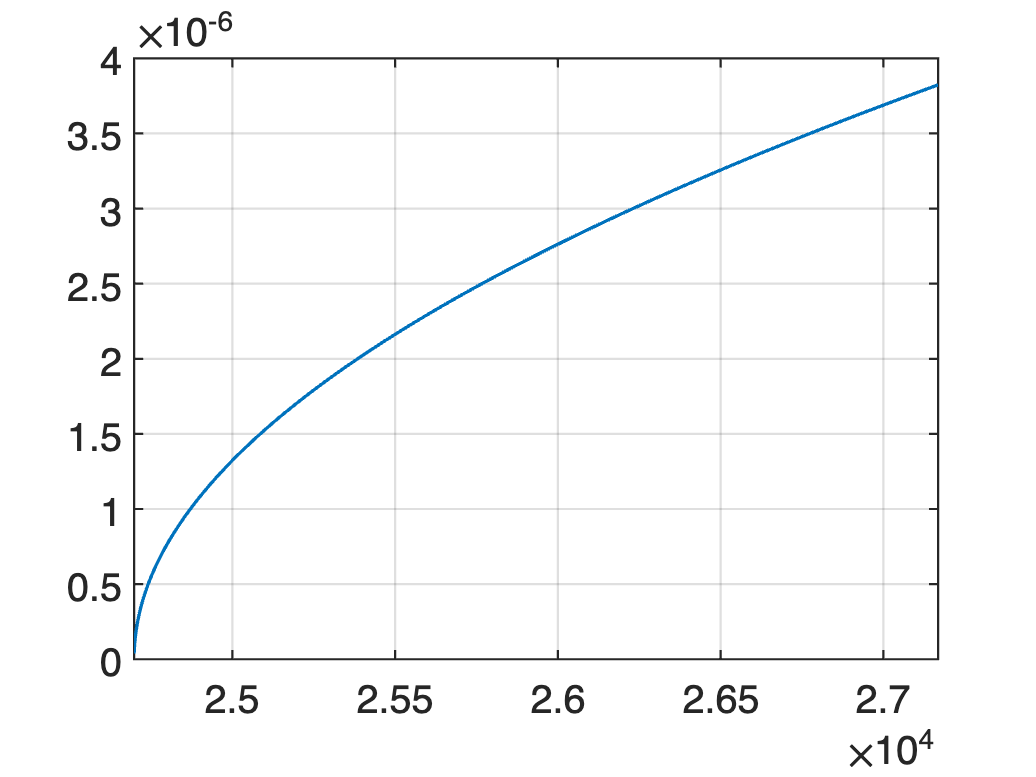

% plot backbone curve
figure; hold on;
plot([BB.Omega]/(2*pi),[BB.Aout],'LineWidth',1.5);
grid on; box on;
set(gca,'FontSize',18); set(gca,'LineWidth',1.0)

## Assignment: extraction of FRC

Use extract_FRC routine to extract the FRC under some external forcing. You are supposed to add external excitations first.